# IIR Filter Design and Implementation

## Design Filter

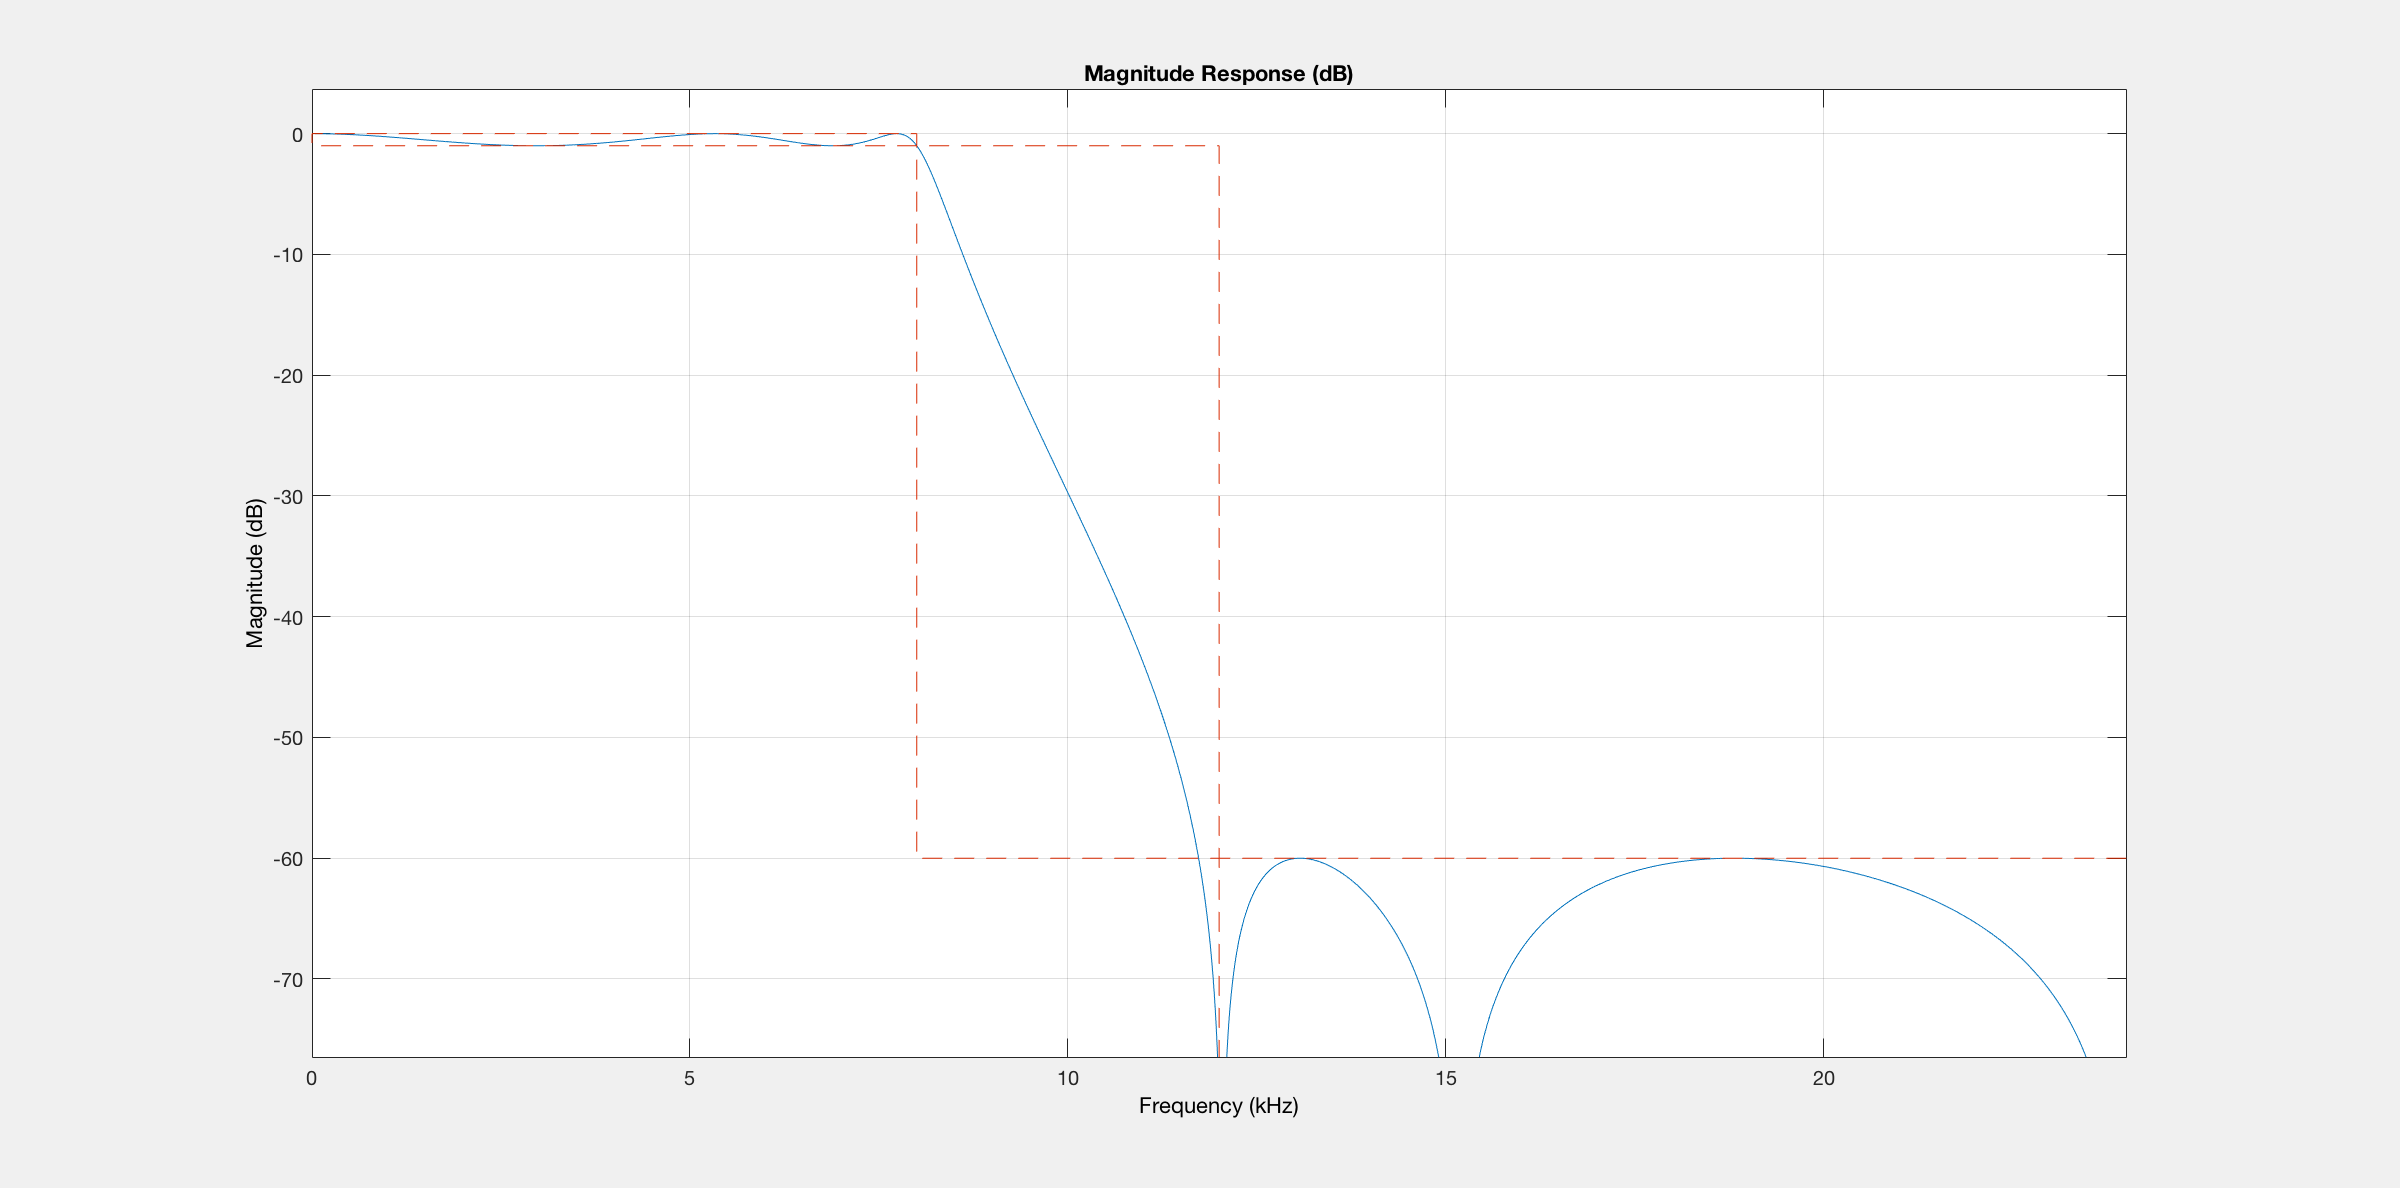

Fpass = 8000;
Fstop = 12000;
Apass = 1;
Astop = 60;
Fs = 48000;

filtSpec = fdesign.lowpass(Fpass, Fstop, Apass, Astop, Fs);
% list possible filter design methods
methods = designmethods(filtSpec);
filt = design(filtSpec, 'ellip');
fvtool(filt);

- Von welcher Ordnung ist das Filter?

N = 5;

- Wo liegen die Pole und Nullstellen des Filters?

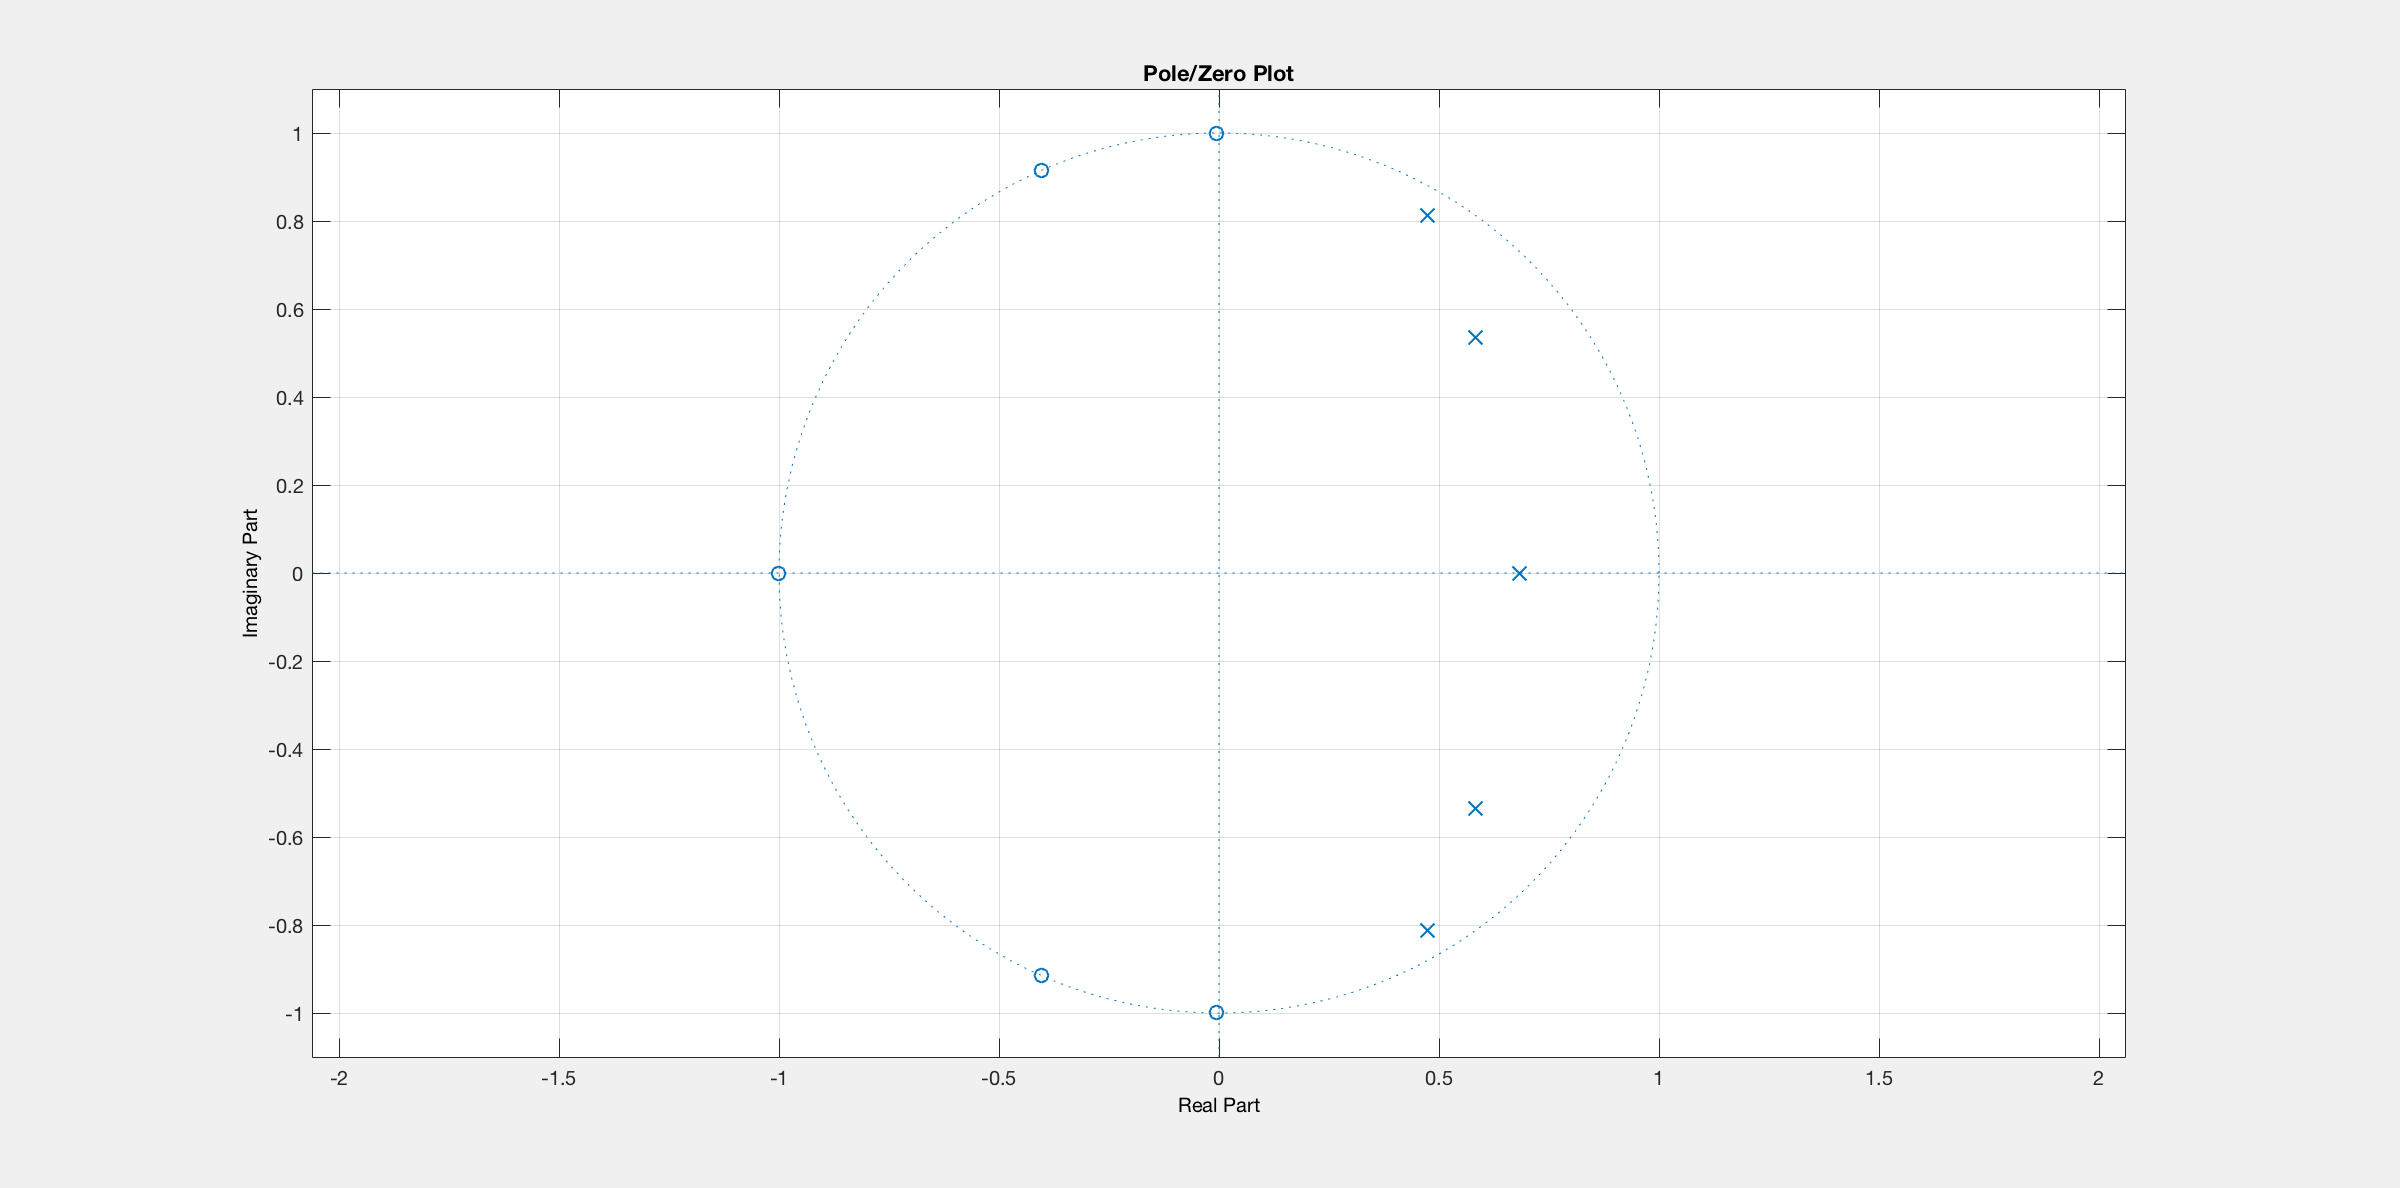

h = fvtool(filt);
h.Analysis = 'polezero';

- Wie sieht die Impulsantwort des Filters aus? 

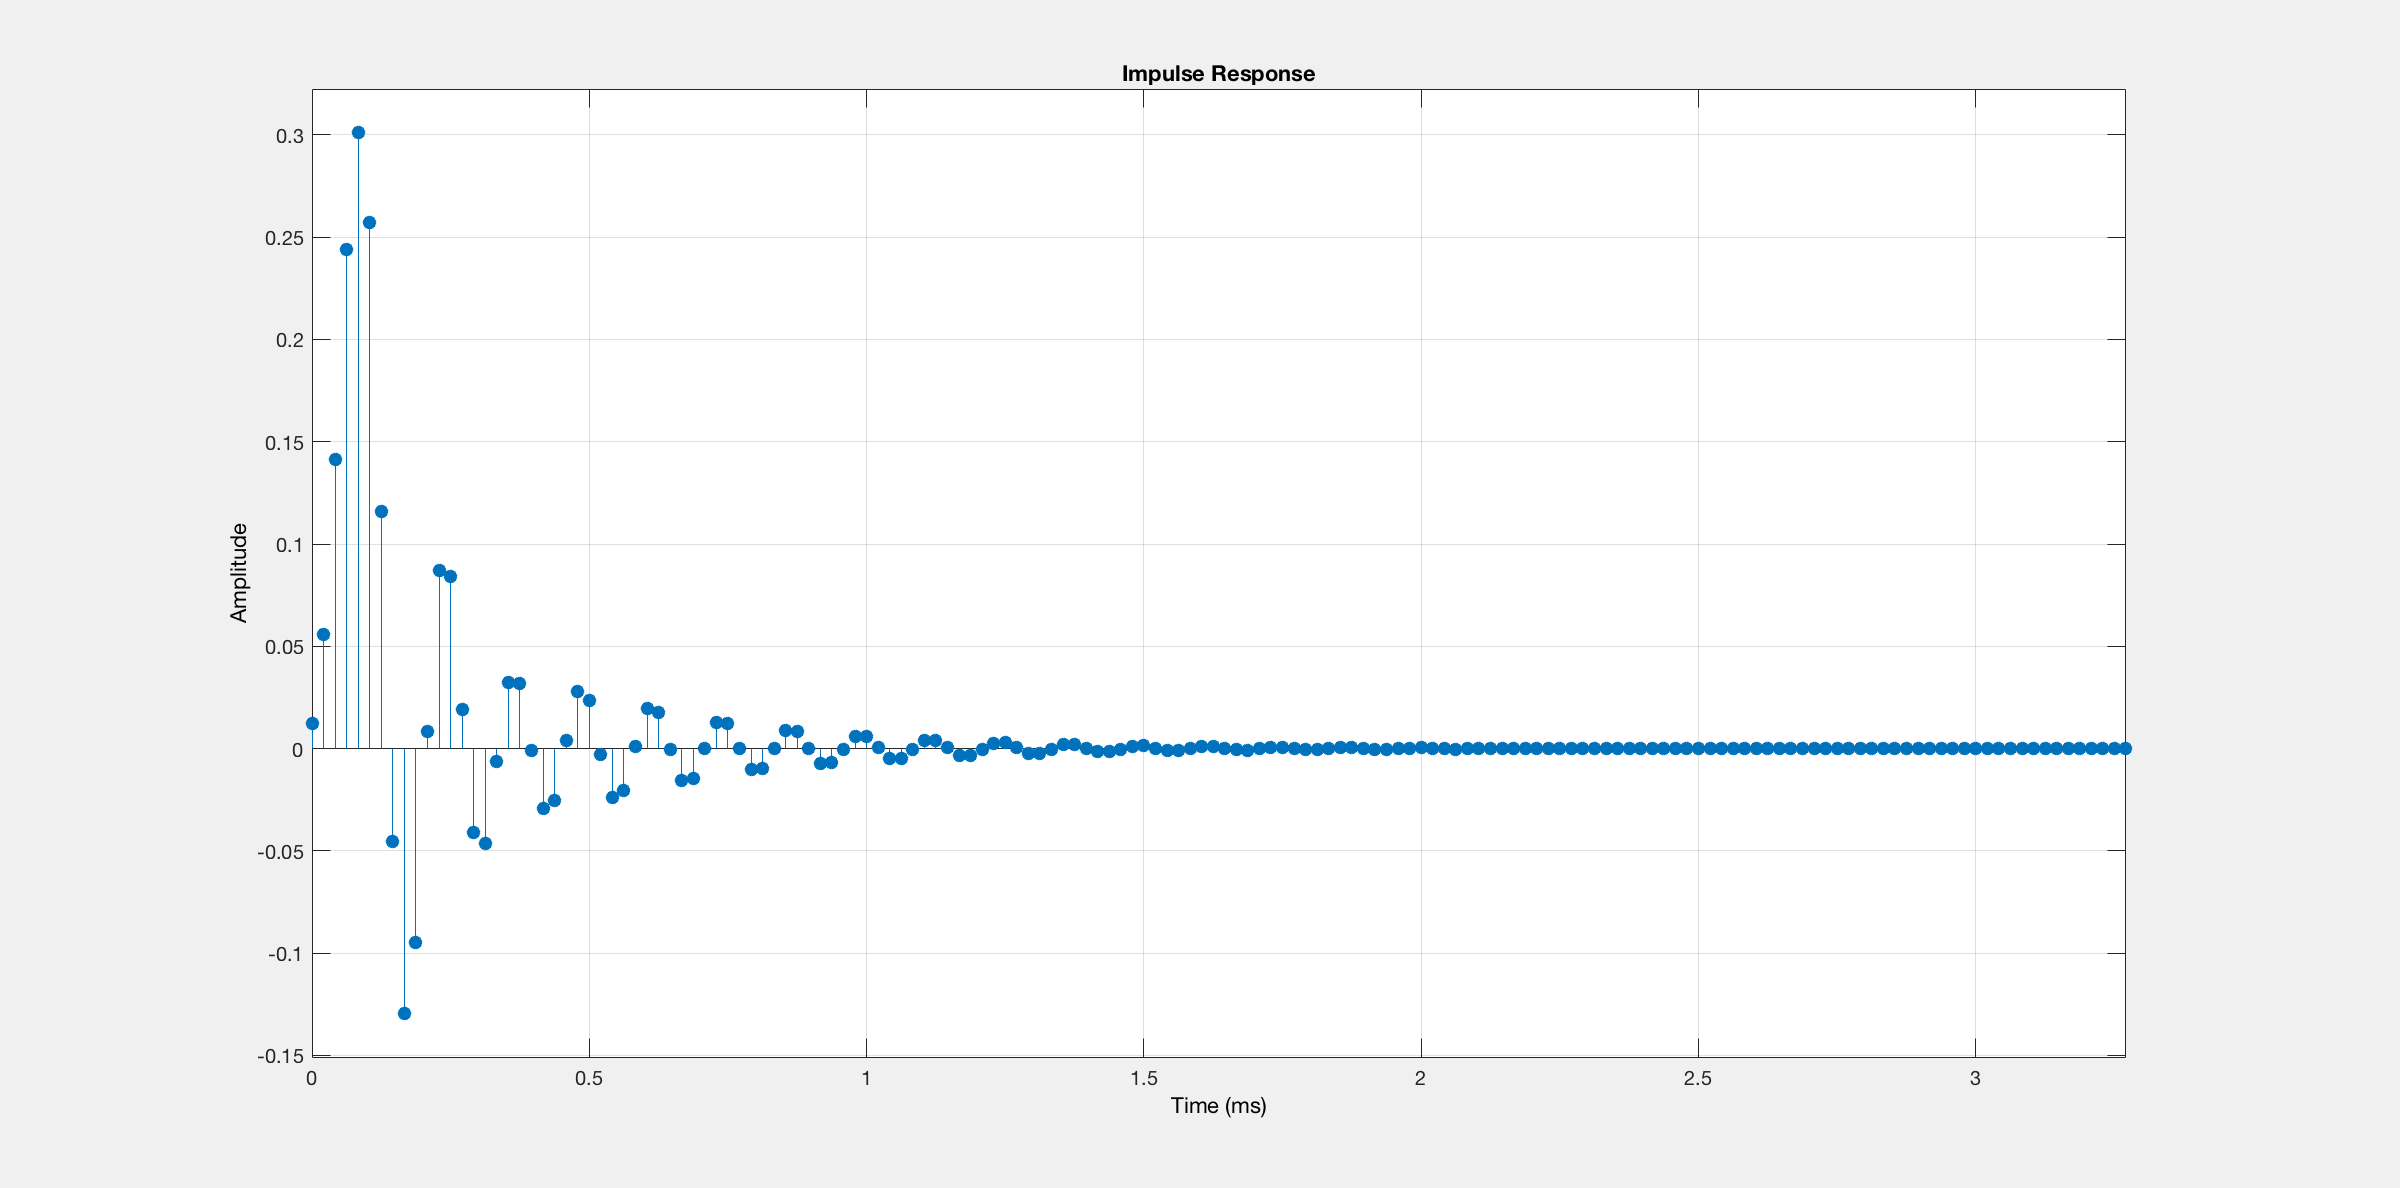

h = fvtool(filt);
h.Analysis = 'impulse';

## Struktur und Skalierung

% Zerlegung in Biquads (second order structures SOS)
SOS = filt.sosMatrix;
G = filt.ScaleValues;

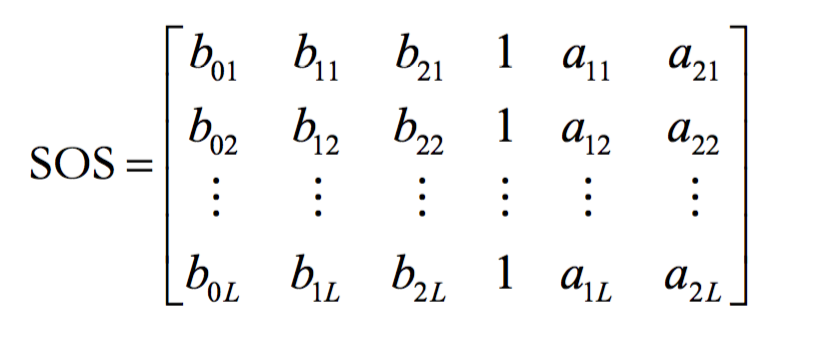

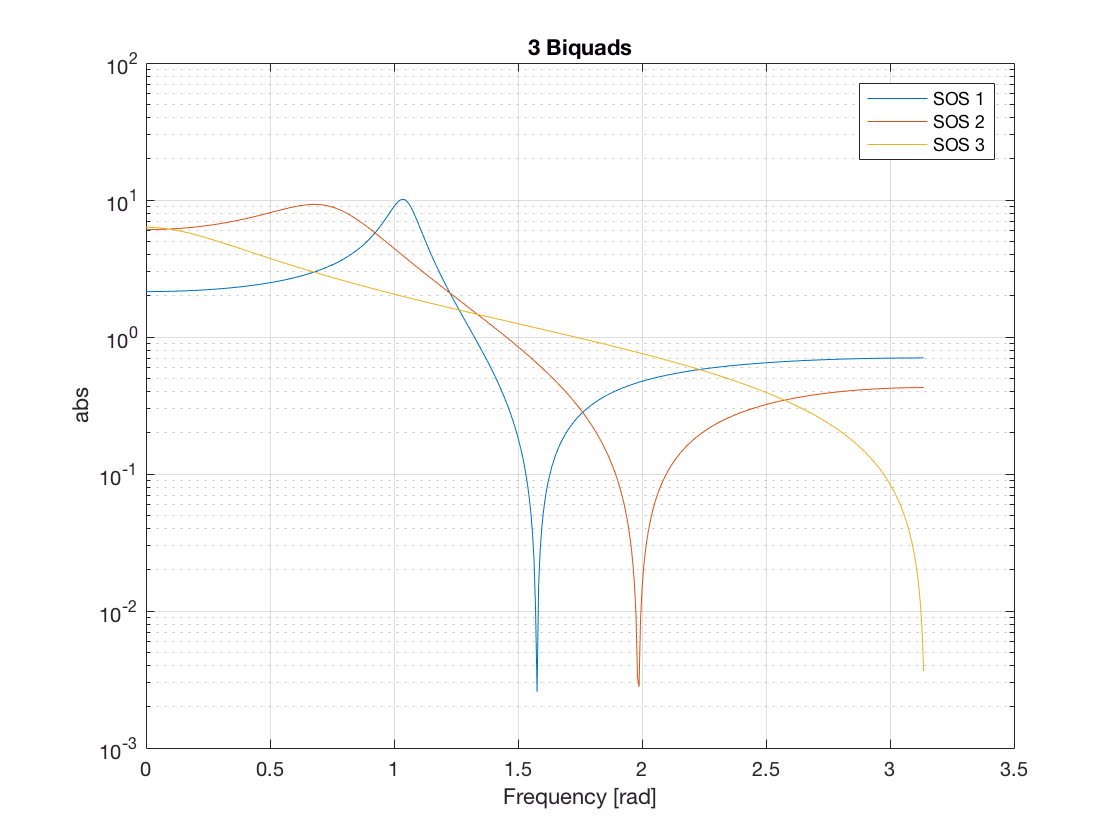

% Biquads extrahieren
b = SOS(:,1:3);
a = SOS(:,4:6);

% frequenzgänge berechnen
[h1, w1] = freqz(b(1,:), a(1,:));
[h2, w2] = freqz(b(2,:), a(2,:));
[h3, w3] = freqz(b(3,:), a(3,:));

% plotten
figure()
semilogy(w1, [abs(h1) abs(h2) abs(h3)])
grid on
title('3 Biquads')
xlabel('Frequency [rad]')
ylabel('abs')
legend('SOS 1','SOS 2','SOS 3')

## Implementierende Reihenfolge

- SOS3

- SOS2

- SOS1

## Skalierung

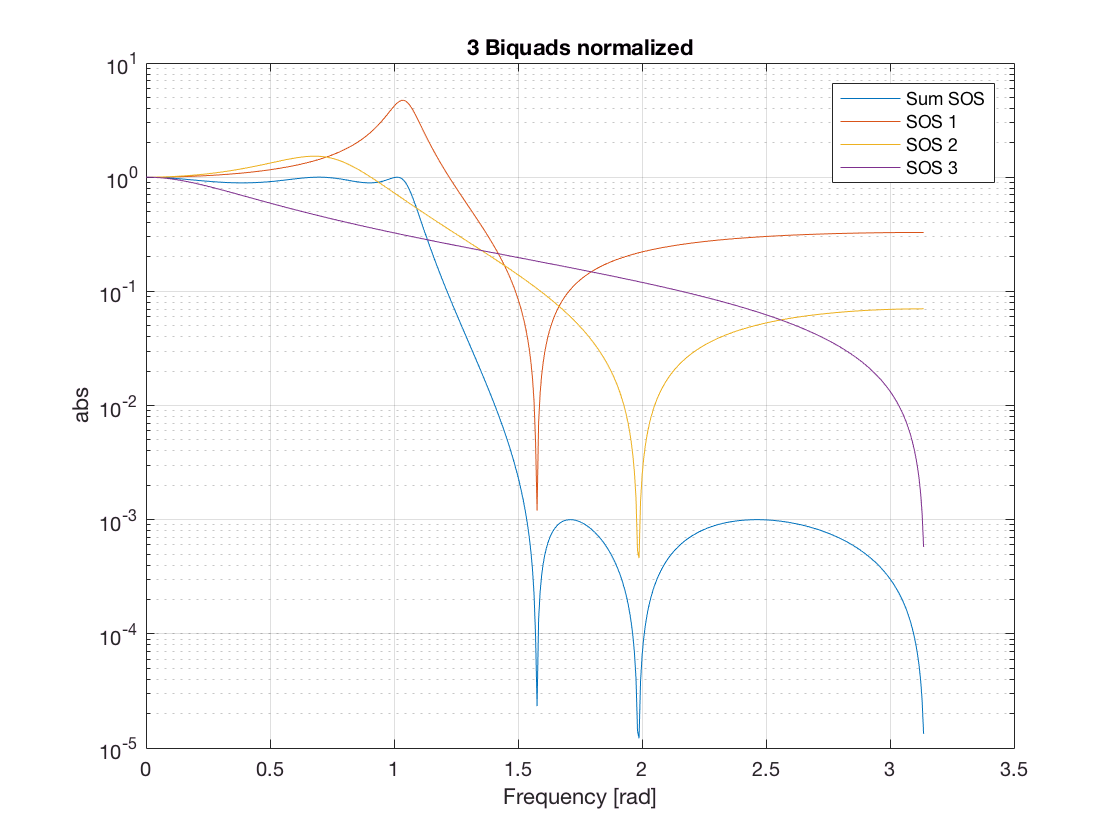

% Maximum gain von SOS3 und skalieren
g3 = max(abs(h3));
b(3,:) = b(3,:) .* 1/g3;
[h3, w3] = freqz(b(3,:), a(3,:));

% Block 1 und 2
g32 = max(abs(h3) .* abs(h2));
b(2,:) = b(2,:) .* 1/g32;
[h2, w2] = freqz(b(2,:), a(2,:));

% Block 1,2 und 3
g321 = max(abs(h3) .* abs(h2) .* abs(h1));
b(1,:) = b(1,:) .* 1/g321;
[h1, w1] = freqz(b(1,:), a(1,:));

% Alle plotten
figure()
semilogy(w1, [ (abs(h1).*abs(h2).*abs(h3))  abs(h1) abs(h2) abs(h3)])
grid on
title('3 Biquads normalized')
xlabel('Frequency [rad]')
ylabel('abs')
legend('Sum SOS','SOS 1','SOS 2','SOS 3')

## SOS zusammensetzen

SOSscaled = [[b(3,:) a(3,:)]; [b(2,:), a(2,:)]; [b(1,:), a(1,:)] ]

SOSscaled =     0.4662    0.0046    0.4662    1.0000   -0.9460    0.8828
    0.1644    0.1324    0.1644    1.0000   -1.1665    0.6278
    0.1582    0.1582         0    1.0000   -0.6836         0


## Umwandlung in Fractional

SOSscaledQ15 = zeros(size(SOSscaled))
for i = 1:numel(SOSscaled)
    SOSscaledQ15(i) = float2q15(SOSscaled(i)./2);
end

% Sort for MPLAB DSP library
[m,n]=size(SOSscaledQ15);
SOSscaledQ15Sorted = zeros(size(SOSscaled))
for i = 1:m
    SOSscaledQ15Sorted(i,1) =  SOSscaledQ15(i,1);
    SOSscaledQ15Sorted(i,2) =  SOSscaledQ15(i,2);
    SOSscaledQ15Sorted(i,3) = -SOSscaledQ15(i,5);
    SOSscaledQ15Sorted(i,4) =  SOSscaledQ15(i,3); 
    SOSscaledQ15Sorted(i,5) = -SOSscaledQ15(i,6); 
end
SOSscaledQ15Sorted